# Construction of New Gait Library (MTA3)

The following MATLAB Live Script builds a a new gait library for the three-limbed MTA soft robot. The first three gaits are translation gaits and the last three gaits are rotation gaits. Each gait is tested for two trials with 60 cycles each. The first trial orients the robot at 0 degrees (yellow marker on the limb pointed to the left) with the tether on the left (denoted "L"). The second trial orients the robot at 180 degrees (yellow marker on the limb pointed to the right) with the tether on the left (denoted "Lf" for "left flipped). No connections/wires or control sequences are changed between the two trials. The two trials are used both to analyze the variance and to reduce any effects / biases caused by the tether positioning or any imperefctions / tilting on the ground.

% Dependencies:
%   +demos/data/visualtracking
%   +offlineanalysis/GaitTest
%   +gaitdef/Gait

% [0] == Script setup
clear; clc; close all

% Add dependencies to classpath
addpath('../');
addpath('data/visualtracking');
addpath('D:\clfreeman7\Documents\Caitlin - Tracking\Vision\MTA3\Gaits\2023127');

% Configure figure tex interpreters
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultTextInterpreter','latex');
set(0, 'DefaultAxesFontSize', 18);

## Extract and define parameters for GaitTest() objects.

#### From 20230127 Experiments:

% Writing the six gait names (A-C are translation, D-F are rotation).
names = 'ABCDEF';
for i = 1:6
    % (L): Robot marker pointed to left, tether on left.
    vid_name = strjoin(["3",names(i),"_60_L"],'');
    gait_names{2*i-1} = strjoin([vid_name,".mat"],'');

    % (Lf): Robot marker pointed to right, tether on left ("left flipped").
    vid_name = strjoin(["3",names(i),"_60_Lf"],'');
    gait_names{2*i} = strjoin([vid_name,".mat"],'');
end

### Build Experiment Matrix

if isrow(gait_names)
    gait_names = gait_names';
end
n_gaits = length(gait_names);

% Extract characteristics of each gait test.
file_names = split(gait_names, '.');
gait_characteristics = cell(n_gaits, 7);
for i = 1:n_gaits
    gait_characteristics(i, 1) = num2cell(i);
    n_underscores = count(gait_names{i}, '_');
    if n_underscores == 4
        gait_characteristics(i, 2:6) = split(file_names(i,1), '_');
        gait_characteristics(i, 7) = num2cell(1);
    else
        gait_characteristics(i, 2:7) = split(file_names(i,1), '_');
    end
end
characteristics = ["Experiment", "Gait", "#Cycles", "Tether", ...
              "Protocol", "Placement", "Trial"];
% Build table.
experiments = cell2table(gait_characteristics, "VariableNames", ...
              characteristics);
sorted_exps = sortrows(experiments, characteristics([2, 4, 5, 6, 7]))
% Construct titles. 
title_components = string(gait_characteristics);
title_components(strcmp(experiments.Tether, 'H'), 4) = 'heavy sheath';

sorted_exps = 69×7 table
    Experiment    Gait     #Cycles     Tether      Protocol    Placement    Trial
    __________    _____    _______    _________    ________    _________    _____

        31        {'B'}    {'60' }    {'32'   }     {'NF'}       {'L'}        1  
        32        {'B'}    {'60' }    {'32'   }     {'NF'}       {'L'}        2  
        33        {'B'}    {'60' }    {'32'   }     {'NF'}       {'R'}        1  
        34        {'B'}    {'60' }    {'32'   }     {'NF'}       {'R'}        2  
        42        {'B'}    {'60' }    {'32SR' }     {'NF'}       {'L'}        1  
        43        {'B'}    {'60' }    {'32SR' }     {'NF'}       {'R'}        1  
        35        {'B'}    {'60' }    {'32SR1'}     {'NF'}       {'R'}        2 

title_components(strcmp(experiments.Tether, 'S'), 4) = 'light sheath';
title_components(strcmp(experiments.Tether, 'NS'), 4) = 'no sheath';
title_components(strcmp(experiments.Tether, '32'), 4) = '32 AWG';
title_components(strcmp(experiments.Tether, '32SR'), 4) = '32 AWG with slip ring';
title_components(strcmp(experiments.Tether, '32SR1'), 4) = '32 AWG with old slip ring';
title_components(strcmp(experiments.Protocol, 'F'), 5) = 'following';
title_components(strcmp(experiments.Protocol, 'NF'), 5) = 'not following';
title_components(strcmp(experiments.Placement, 'L'), 6) = 'left';
title_components(strcmp(experiments.Placement, 'R'), 6) = 'right';
title_components = [repmat(["Experiment" ":" "cycles of Gait" "with" "tether (" "," ")," "trial"], n_gaits, 1) title_components];
title_matrix = title_components(:, [1,9,2,11,3,10,4,12,5,14,6,13,7,8,15]);
exp_title = join(title_matrix);
% Define experimental parameters after investigating videos. 
frame_start_list(1:6) = [,,,,,];
frame_start_list(7:12) = [,,,,,];

% Find marker order by investigating first frame.
marker_order_list = repmat([1 2 3 4 5 6],n_gaits, 1);
%marker_order_list([2,3,43],:) = repmat([1 4 3 2],3,1);
%marker_order_list([8,9,10,21,25,31,34,40,41,44,50,53,54,57,58,61,63,64,65,66,67],:) = repmat([2 4 3 1],21,1);
%marker_order_list([12,14,16],:) = repmat([4 2 1 3],3,1);
%marker_order_list([26, 35,46,47,56],:) = repmat([2,3,4,1],5,1);

show_markers = true;     % plots first frame of each video

% Initialize the stability experiment struct. 
stab_exp = struct('params', [], 'raw_data', []);
gait_sequences = cell(n_gaits,1);

% Extract data.
for i = 1:n_gaits
    % Define robot / experiment parameters.
    stab_exp(i).params.robot_name = 'MTA3';
    stab_exp(i).params.substrate = 'black mat';
    stab_exp(i).params.n_markers = 6;
    stab_exp(i).params.pixel_length = 1/8.6343;     % cm per pixel

    % Define number of gait cycles run.
    stab_exp(i).params.n_cycles= str2double(gait_characteristics{i,3}); 
         % accounts for pause after first cycle in some of the videos

    % Extract and store first frame information.
    stab_exp(i).params.frame_1 = frame_start_list(i);
    stab_exp(i).params.marker_order = marker_order_list(i,:);
    
    % Extract and store raw data from each trial
    filename = gait_names{i};
    stab_exp(i).raw_data = load(filename).tracking_data;  
    if experiments.Gait{i} == 'B'
        gait_sequences{i} = [16,7,5,11,14];   % Gait B (rotational)
    elseif experiments.Gait{i} == 'E'
        gait_sequences{i} = [9,16,1];         % Gait E (translational)
    elseif experiments.Gait{i} == 'Bs'
        gait_sequences{i} = [8,7,5,3,6];
    elseif experiments.Gait{i} == 'Es' 
        gait_sequences{i} = [9,12,1];
     elseif experiments.Gait{i} == 'F'
        gait_sequences{i} = [9 14 8 1];
    elseif experiments.Gait{i} == 'G' 
        gait_sequences{i} = [3 15 1];
    elseif experiments.Gait{i} == 'H'
        gait_sequences{i} = [7 12 13 2];
    elseif experiments.Gait{i} == 'I'
        gait_sequences{i} = [2 8 1];
    elseif experiments.Gait{i} == 'J'
        gait_sequences{i} = [9 12 1];
    elseif experiments.Gait{i} == 'K'
        gait_sequences{i} = [5 14 1];
    else
        gait_sequences{i} = [];
    end
    gait_sequences{4} = [1, 16, 1];
end

## Analyze the experiment data:

#### 1. Rotate the data w.r.t. the initial global orientation.

% Define first experiment first frame orientation as theta = 0. 
markers_x(1, :) = stab_exp(1).raw_data(1, 1:3:stab_exp(1).params.n_markers*3-2);
markers_y(1, :) = stab_exp(1).raw_data(1, 2:3:stab_exp(1).params.n_markers*3-1);
centroid(:, :, 1) = mean([markers_x(1, :); markers_y(1, :)], 2);
% Move initial position to (0,0) origin.
reference_markers = [markers_x(1, [1 3 4 2]); markers_y(1, [1 3 4 2]);]...
                    - centroid(:, :, 1);
% For each trial, rotate data to align first frame global orientations.
 for i = 1:n_gaits
    % Find initial rotation matrix for each trial to have consistent fixed frame.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
    centroid(:, :, i) = mean([markers_x(i, :); markers_y(i, :)], 2);

    % Move initial position to (0,0) origin.
    shifted_markers = [markers_x(i, stab_exp(i).params.marker_order);
                       markers_y(i, stab_exp(i).params.marker_order)]...
                       - centroid(:, :, i);

    % Find orientation of subsequent trials w.r.t. first trial GCS.
    [regParams,~,~] = absor(reference_markers, shifted_markers);
    stab_exp(i).params.R_1 = [regParams.R zeros(2,1); 0 0 1];
 end


#### 2. Instantiate GaitTest() objects for each experimental trial.

 %This analyzes the data from each trial to find motion primitive twist information.
% Instantiate objects for each gait tested. 
all_gaits = offlineanalysis.GaitTest.empty(0,n_gaits); 
gait_defs = gaitdef.Gait.empty(0,n_gaits);
tail_idx = cell(n_gaits, 1);
head_idx = cell(n_gaits, 1);
delta_poses = cell(n_gaits,1);
global_theta = cell(n_gaits,1);
twists = cell(n_gaits,1);
cent_rot = cell(n_gaits,1);
rad_curv = cell(n_gaits,1);

#### 3. Calculate twists for each gait experiment.

% Calculate twists for each gait experiment.
for i = 1:n_gaits
    all_gaits(i) = offlineanalysis.GaitTest(stab_exp(i).raw_data, ...
                                                 gait_sequences{i}(1,:), ...
                                                 stab_exp(i).params);
    gait_defs(i) = gaitdef.Gait(all_gaits(i), stab_exp(i).params);
    % Manually find the twists. 
    % Extract gait / experiment details. 
    n_cycles = all_gaits(i).n_cycles;
    len_gait = all_gaits(i).len_gait;
     for j = 1:n_cycles - 1
         % Record indexes for each motion primitive tail and head. 
         tail_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*(j-1)+2);
         head_idx{i}(1,j) = all_gaits(i).keyframes(len_gait*j+2);

         % Find change in poses w.r.t. global inertial frame for each motion primitive. 
         delta_poses{i}(:,j) = all_gaits(i).raw_poses(:, head_idx{i}(1,j)) - all_gaits(i).raw_poses(:, tail_idx{i}(1,j));
         delta_poses{i}(1:2,j) = all_gaits(i).pixel_length*delta_poses{i}(1:2,j);

         % Find global orientation of robot at each motion primitive tail. 
         global_theta{i}(:,j) = all_gaits(i).raw_poses(3, tail_idx{i}(1,j));

         % Convert from global frame to body frame.  
         rot_mat =  [cos(global_theta{i}(1,j)) -sin(global_theta{i}(1,j)); sin(global_theta{i}(1,j)) cos(global_theta{i}(1,j))];
         delta_poses{i}(1:2,j) = rot_mat'*delta_poses{i}(1:2,j);
         R =  [cos(delta_poses{i}(3,j)) -sin(delta_poses{i}(3,j)); sin(delta_poses{i}(3,j)) cos(delta_poses{i}(3,j))];
         % Convert to twists.
         twists{i}(:,j)  = gait_defs(i).delta_pose_2_twist(delta_poses{i}(:,j), all_gaits(i).transition_time*len_gait);

         % Find instantaneous center of rotation.
         cent_rot{i}(:,j) = (eye(2) - R)\delta_poses{i}(1:2, j);

         % Find instantaneous radius of curvature.
         rad_curv{i}(1,j) = norm(cent_rot{i}(:,j));
     end
     
end


## Construct comparative ICR / ROC plots.

## Make gait libraries.

% Gait B ( 32AWG, new slip ring).
gait_library_4(1) = gaitdef.Gait(all_gaits([42,43]));
gait_library_4(1).robot_name = 'orange';
gait_library_4(1).tether = '32SR';
gait_library_4(1).tether_protocol = {'NF (left)','NF (right)'};
gait_library_4(1).gait_name = 'B';
% Gait G ( 32AWG, new slip ring).
gait_library_4(2) = gaitdef.Gait(all_gaits([50,51,58,59,66]));
gait_library_4(2).robot_name = 'orange';
gait_library_4(2).tether = '32SR';
gait_library_4(2).tether_protocol = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
gait_library_4(2).gait_name = 'G';
% Gait I ( 32AWG, new slip ring).
gait_library_4(3) = gaitdef.Gait(all_gaits([52,53,60,61,67]));
gait_library_4(3).robot_name = 'orange';
gait_library_4(3).tether = '32SR';
gait_library_4(3).tether_protocol = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
gait_library_4(3).gait_name = 'I';
% Gait J ( 32AWG, new slip ring).
gait_library_4(4) = gaitdef.Gait(all_gaits([54,55,62,63,68]));
gait_library_4(4).robot_name = 'orange';
gait_library_4(4).tether = '32SR';
gait_library_4(4).tether_protocol = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
gait_library_4(4).gait_name = 'J';
% Gait K ( 32AWG, new slip ring).
gait_library_4(5) = gaitdef.Gait(all_gaits([56,57,64,65,69]));
gait_library_4(5).robot_name = 'orange';
gait_library_4(5).tether = '32SR';
gait_library_4(5).tether_protocol = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
gait_library_4(5).gait_name = 'K';


## Plot gait libraries.

%%
figure
plot_trajs(gait_library_4, 1:5, {'B','G','I','J','K'}, 10,60)
save data/gait_library_4 gait_library_4


## Construct comparative motion plots.

Comparison (overlay) of 2 trials of gait B (AWG 32 with new slip ring):

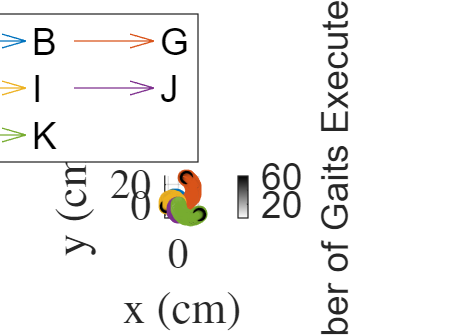

figure
trial_nums_B_32SR = [42,43];

trial_labels_B_32SR = {'NF (left)', 'NF (right)'};
plot_trajs(all_gaits, trial_nums_B_32SR, trial_labels_B_32SR, 15)
hold on
plot_trajs(gait_library_4, 1, {'Average'}, 15,60,'k')
ax = gca;
lgd_idxs = [];
for i = 1:4:length(ax.Children)
    lgd_idxs = [lgd_idxs ax.Children(i)];
end
legend(flip(lgd_idxs),{'NF (left)','NF (right)','Average'})

Comparison (overlay) of 5 trials of gait G (AWG 32 with slip ring):

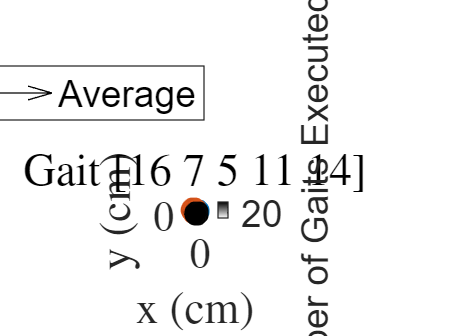

figure
trial_nums_G_32SR = [50,51,58,59,66];
trial_labels_G_32SR = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
plot_trajs(all_gaits, trial_nums_G_32SR, trial_labels_G_32SR, 15)
hold on
plot_trajs(gait_library_4, 2, {'G'}, 15,60,'k')

ax = gca;
lgd_idxs = [];
for i = 1:4:length(ax.Children)
    lgd_idxs = [lgd_idxs ax.Children(i)];
end
legend(flip(lgd_idxs),{'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})

Comparison (overlay) of 5 trials of gait I (AWG 32 with new slip ring):

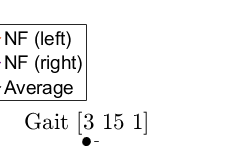

figure
trial_nums_I_32SR = [52,53,60,61,67];
trial_labels_I_32SR = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
plot_trajs(all_gaits, trial_nums_I_32SR, trial_labels_I_32SR, 15)
hold on
plot_trajs(gait_library_4, 3, {'H'}, 15,60,'k')

ax = gca;
lgd_idxs = [];
for i = 1:4:length(ax.Children)
    lgd_idxs = [lgd_idxs ax.Children(i)];
end
legend(flip(lgd_idxs),{'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})

Comparison (overlay) of 5 trials of gait J (AWG 32 with new slip ring):

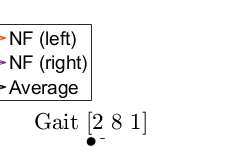

figure
trial_nums_J_32SR = [54,55,62,63,68];
trial_labels_J_32SR = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
plot_trajs(all_gaits, trial_nums_J_32SR, trial_labels_J_32SR, 15)
hold on
plot_trajs(gait_library_4, 4, {'J'}, 15,60,'k')

ax = gca;
lgd_idxs = [];
for i = 1:4:length(ax.Children)
    lgd_idxs = [lgd_idxs ax.Children(i)];
end
legend(flip(lgd_idxs),{'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})

Comparison (overlay) of 5 trials of gait K (AWG 32 with new slip ring):

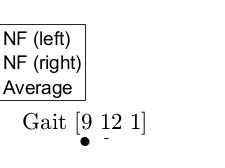

figure
trial_nums_K_32SR = [56,57,64,65,69];
trial_labels_K_32SR = {'NF (left)','NF (left)','NF (right)','NF (right)','NF (left)'};
plot_trajs(all_gaits, trial_nums_K_32SR, trial_labels_K_32SR, 15)
hold on
plot_trajs(gait_library_4, 5, {'K'}, 15,60,'k')

ax = gca;
lgd_idxs = [];
for i = 1:4:length(ax.Children)
    lgd_idxs = [lgd_idxs ax.Children(i)];
end
legend(flip(lgd_idxs),{'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})

## Construct comparative twist plots.

Twist comparison for 2 trials of gait B (AWG 32 with new slip ring):

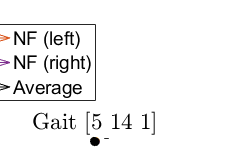

twists_plot =plot_twists(twists, global_theta, trial_nums_B_32SR, trial_labels_B_32SR,[0 0.6;0 0.6; 0.06 0.12; 0 0.6; 0 0.6; 0.06 0.12 ]);
hold on
nexttile(1)
plot(1:60, gait_library_4(1).Twist(1)*ones(60,1),'k');
nexttile(3)

plot(1:60, gait_library_4(1).Twist(2)*ones(60,1),'k');
nexttile(5)
plot(1:60, gait_library_4(1).Twist(3)*ones(60,1),'k');
nexttile(2)
plot([-180, 180],gait_library_4(1).Twist(1)*ones(2,1),'k')
nexttile(4)
plot([-180, 180],gait_library_4(1).Twist(2)*ones(2,1),'k')
nexttile(6)
plot([-180, 180],gait_library_4(1).Twist(3)*ones(2,1),'k')
legend({'NF (left)','NF (right)','Average'})
t = title(twists_plot, 'Gait B Twists');
t.FontSize = 20;
t.Interpreter = 'latex';

Twist comparison for 5 trials of gait G (AWG 32 with new slip ring):

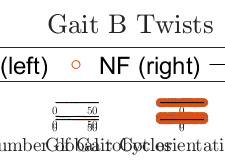

twists_plot = plot_twists(twists, global_theta, trial_nums_G_32SR, trial_labels_G_32SR,[0 0.6; -.3 .3; 0 0.05; 0 0.6; -.3 .3; 0 0.06]);
hold on
nexttile(1)
plot(1:60, gait_library_4(2).Twist(1)*ones(60,1),'k');
nexttile(3)
plot(1:60, gait_library_4(2).Twist(2)*ones(60,1),'k');

nexttile(5)
plot(1:60, gait_library_4(2).Twist(3)*ones(60,1),'k');
nexttile(2)
plot([-180, 180],gait_library_4(2).Twist(1)*ones(2,1),'k')
nexttile(4)
plot([-180, 180],gait_library_4(2).Twist(2)*ones(2,1),'k')
nexttile(6)
plot([-180, 180],gait_library_4(2).Twist(3)*ones(2,1),'k')
legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
t = title(twists_plot, 'Gait G Twists');
t.FontSize = 20;
t.Interpreter = 'latex';

Twist comparison for 5 trials of gait I (AWG 32 with new slip ring):

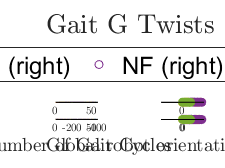

twists_plot = plot_twists(twists, global_theta, trial_nums_I_32SR, trial_labels_I_32SR,[-.3 .3; -.2 .4; .01 .07; -.3 .3; .15 .4; .01 .07]);
hold on
nexttile(1)
plot(1:60, gait_library_4(3).Twist(1)*ones(60,1),'k');
nexttile(3)
plot(1:60, gait_library_4(3).Twist(2)*ones(60,1),'k');

nexttile(5)
plot(1:60, gait_library_4(3).Twist(3)*ones(60,1),'k');
nexttile(2)
plot([-180, 180],gait_library_4(3).Twist(1)*ones(2,1),'k')
nexttile(4)
plot([-180, 180],gait_library_4(3).Twist(2)*ones(2,1),'k')
nexttile(6)
plot([-180, 180],gait_library_4(3).Twist(3)*ones(2,1),'k')
legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
t = title(twists_plot, 'Gait I Twists');
t.FontSize = 20;
t.Interpreter = 'latex';

Twist comparison for 5 trials of gait J (AWG 32 with new slip ring):

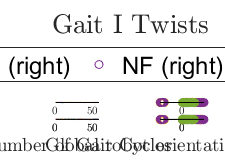

twists_plot = plot_twists(twists, global_theta, trial_nums_J_32SR, trial_labels_J_32SR,[-.5 .1;-.5 .1;.01 .07; -.5 .1;-.5 .1;.01 .07]);
hold on
nexttile(1)
plot(1:60, gait_library_4(4).Twist(1)*ones(60,1),'k');
nexttile(3)
plot(1:60, gait_library_4(4).Twist(2)*ones(60,1),'k');

nexttile(5)
plot(1:60, gait_library_4(4).Twist(3)*ones(60,1),'k');
nexttile(2)
plot([-180, 180],gait_library_4(4).Twist(1)*ones(2,1),'k')
nexttile(4)
plot([-180, 180],gait_library_4(4).Twist(2)*ones(2,1),'k')
nexttile(6)
plot([-180, 180],gait_library_4(4).Twist(3)*ones(2,1),'k')
legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
t = title(twists_plot, 'Gait J Twists');
t.FontSize = 20;
t.Interpreter = 'latex';

Twist comparison for 5 trials of gait K (AWG 32 with new slip ring):

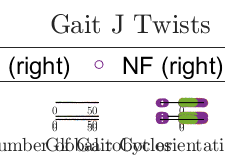

twists_plot = plot_twists(twists, global_theta, trial_nums_K_32SR, trial_labels_K_32SR,[-.3 .3;-.6 0;0 .06; -.3 .3;-.6 0;0 .06]);
hold on
nexttile(1)
plot(1:60, gait_library_4(5).Twist(1)*ones(60,1),'k');
nexttile(3)
plot(1:60, gait_library_4(5).Twist(2)*ones(60,1),'k');

nexttile(5)
plot(1:60, gait_library_4(5).Twist(3)*ones(60,1),'k');
nexttile(2)
plot([-180, 180],gait_library_4(5).Twist(1)*ones(2,1),'k')
nexttile(4)
plot([-180, 180],gait_library_4(5).Twist(2)*ones(2,1),'k')
nexttile(6)
plot([-180, 180],gait_library_4(5).Twist(3)*ones(2,1),'k')
legend({'NF (left)','NF (left)','NF (right)','NF (right)','NF (left,30 cycles)','Average'})
t = title(twists_plot, 'Gait K Twists');
t.FontSize = 20;
t.Interpreter = 'latex';

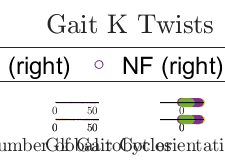


if show_markers
    figure
    %tiledlayout(5,6)
    tiledlayout(3,4)
 
    pic_name = gait_names{i};

    pic_name(end-3:end) = [];
    % Plot first image of experiment video.
    file_name = ['data/visualtracking/firstframe_', pic_name, '.jpg'];
    pic = imread(file_name);
    nexttile;
    imshow(pic)
    hold on
    
    % Plot labeled (i.e., numbered) markers on top of image.
    markers_x(i, :) = stab_exp(i).raw_data(1, 1:3:stab_exp(i).params.n_markers*3-2);
    markers_y(i, :) = stab_exp(i).raw_data(1, 2:3:stab_exp(i).params.n_markers*3-1);
%     if iTrial ~=5
    for m = 1:stab_exp(i).params.n_markers
        text(markers_x(i, m), 1080-markers_y(i, m), num2str(m),'Color','white','FontSize',14);
%     end
    end
    
    % Adjust size.
     xlim([min(markers_x(i, :))-200, max(markers_x(i, :))+200]);
     ylim([min(1080 - markers_y(i, :)) - 200, max(1080 - markers_y(i, :))+200]);
    
    
    end
end


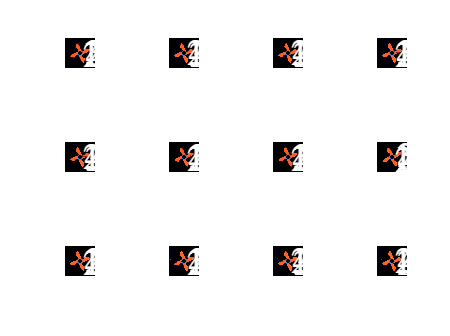

function plot_trajs(all_gaits, trial_nums, trial_labels, marker_size, n_cycles, color_array)
if nargin<5
    n_cycles = [];
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE"];
end
if nargin<6
    color_array = ["#0072BD", "#D95319", "#EDB120", "#7E2F8E", "#77AC30", "#4DBEEE"];
end

k = 1;
lgd_idxs = [];
for i = trial_nums
    if isempty(n_cycles)
        all_gaits(i).plot;
    else
        all_gaits(i).plot(n_cycles);
    end
    ax = gca;
    ax.Children(1).Color = color_array(k);
    ax.Children(2).MarkerEdgeColor = "none";
    ax.Children(2).MarkerFaceColor = color_array(k); 
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(2).MarkerFaceAlpha = .3;
    ax.Children(3).MarkerEdgeColor = color_array(k);
    ax.Children(3).MarkerEdgeAlpha = .8;
    ax.Children(4).Color = color_array(k);
    if ~isempty(marker_size)
        ax.Children(2).SizeData = marker_size;
    end
    k = k+1;
    lgd_idxs = [lgd_idxs ax.Children(1)];
end
colormap(flip(gray))
a = colorbar;
a.Location = "eastoutside";
a.Label.String = 'Number of Gaits Executed';
lgd = legend(lgd_idxs, trial_labels);
lgd.Location = "northoutside";
lgd.Orientation = "horizontal";
if length(trial_nums)>2
    lgd.NumColumns = 2;
end
end

function twists_plot = plot_twists(twists, global_theta, trial_nums, trial_labels, ylims)
    figure;
    twists_plot = tiledlayout(3,2);
    ylabels = {'$v_x$ (cm/s)', '$v_y$ (cm/s)', '$\omega$ (deg/s)'};

    % Plot twist components vs number of gait cycles.
    for i = 1:3
        nexttile(2*i - 1);
        hold on;
        for j = 1:length(trial_nums)        
            plot(twists{trial_nums(j)}(i,:))
        end
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(i,:))
        end
    end
    xlabel('Number of Gait Cycles', 'FontSize',14)
    
    % Plot twist components vs global robot orientation.
    for i = 1:3
        nexttile(2*i);
        hold on;
        for j = 1:length(trial_nums)        
            scatter(rad2deg(global_theta{trial_nums(j)}(1,:)),twists{trial_nums(j)}(i,:))
        end
        xlim([-180 180])
        ylabel(ylabels{i}, 'FontSize',14)
        if ~isempty(ylims)
            ylim(ylims(3+i,:))
        end
    end
    xlabel('Global robot orientation $\theta_G$ (deg)', 'FontSize',14)

    if length(trial_labels) > 1
        lgd = legend(trial_labels, 'FontSize',18);
        lgd.Orientation = 'horizontal';
        lgd.Layout.Tile = 'north';
    else
        plot_title = ['Twist (body velocity) for', trial_labels];
        title(twists_plot,plot_title, 'FontSize',22) 
    end
end

function plot_ICR(cent_rot, rad_curv, trial_nums, trial_labels, ylims)
figure
tiledlayout(2,1)
for i = trial_nums
    nexttile(1)
    hold on;
    scatter(cent_rot{i}(1,:), cent_rot{i}(2,:),'*')
    nexttile(2)
    hold on;
    plot(1:length(rad_curv{i}(1,:)), rad_curv{i}(1,:))
end
nexttile(1)
title('Instantaneous center of rotation IC')
xlabel('x (cm)')
if ~isempty(ylims)
    ylim(ylims(1,:))
end
ylabel('y (cm)')
daspect([1 1 1]);
nexttile(2)
if ~isempty(ylims)
    ylim(ylims(2,:))
end
lgd = legend(trial_labels, 'Orientation', 'Horizontal');
lgd.Layout.Tile = 'north';

title('Radius of curvature')
xlabel('Number of Gait Cycles')
ylabel('$\| IC\|  (cm)$')
end